# Cinematica diretta robot RRR planare

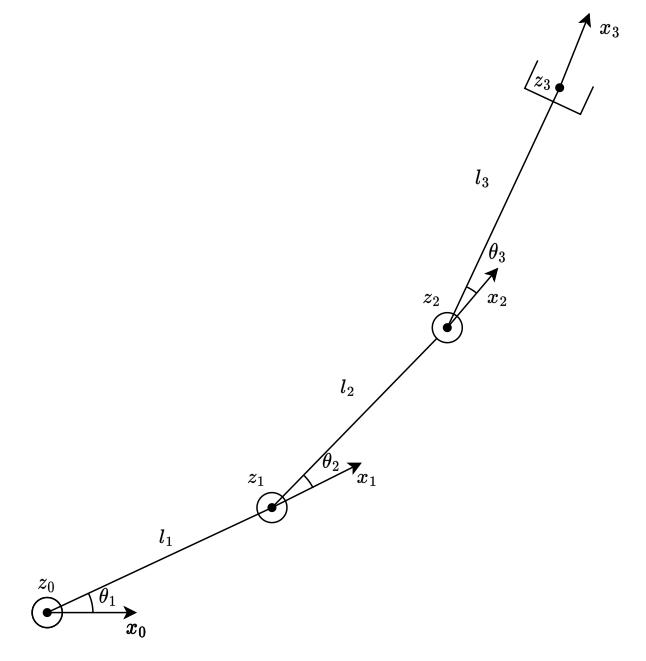

syms q1 q2 q3 l1 l2 l3 real
DHRRRplanare = [l1, 0, 0, q1;
             l2, 0, 0, q2;
             l3, 0, 0, q3]

$$DHRRRplanare = \left(\begin{array}{cccc} l_{1} & 0 & 0 & q_{1}\\ l_{2} & 0 & 0 & q_{2}\\ l_{3} & 0 & 0 & q_{3} \end{array}\right)$$

TRRRplanareList = cinDirDH(DHRRRplanare);
T01 = TRRRplanareList{1}

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & l_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = TRRRplanareList{2}

$$T12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & l_{2}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & l_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = TRRRplanareList{3}

$$T23 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & l_{3}\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & l_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03 = TRRRplanareList{4}

$$T03 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+l_{3}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sigma_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$